# OGLO notebook 4f

hnxj@github

## Cross area relations

nPath = "lfpData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));
pgxx = zeros(10, 12, 1024, 141);

for i = 11:20

    nFile = nFiles{i};
    a = load(nPath + nFile);
    b = struct2cell(a);
    pgxx(i-10, :, :, :) = b{1};
    disp(num2str(i) + ". loaded : " + nFile);

end

11. loaded : TFRs01_OGLO_V1.mat
12. loaded : TFRs02_OGLO_V2.mat
13. loaded : TFRs03_OGLO_V3a.mat
14. loaded : TFRs04_OGLO_V3d.mat
15. loaded : TFRs05_OGLO_V4.mat
16. loaded : TFRs06_OGLO_TEO.mat
17. loaded : TFRs07_OGLO_MT.mat
18. loaded : TFRs08_OGLO_mst.mat
19. loaded : TFRs09_OGLO_FEF.mat
20. loaded : TFRs10_OGLO_PFC.mat


pgxg = zeros(10, 12, 4, 141);
 
for ik = 1:10

    for jk = 1:12

        for kk = 1:size(pgxx, 3)

            pgxx(ik, jk, kk, :) = pgxx(ik, jk, kk, :)/(mean(pgxx(ik, jk, kk, 1:10)));

        end

        pgxg(ik, jk, 1, :) = smooth(squeeze(mean(pgxx(ik, jk, 15:60, :), 3)), 1);
        pgxg(ik, jk, 2, :) = smooth(squeeze(mean(pgxx(ik, jk, 80:120, :), 3)), 1);
        pgxg(ik, jk, 3, :) = smooth(squeeze(mean(pgxx(ik, jk, 125:320, :), 3)), 1);
        pgxg(ik, jk, 4, :) = smooth(squeeze(mean(pgxx(ik, jk, 360:end, :), 3)), 1);

    end

end

>Temporal offset

>Alpha/Beta separate plots

>Gamma separate plots

>Spiking PFC/FEF to LFP other areas

Temporal comparison

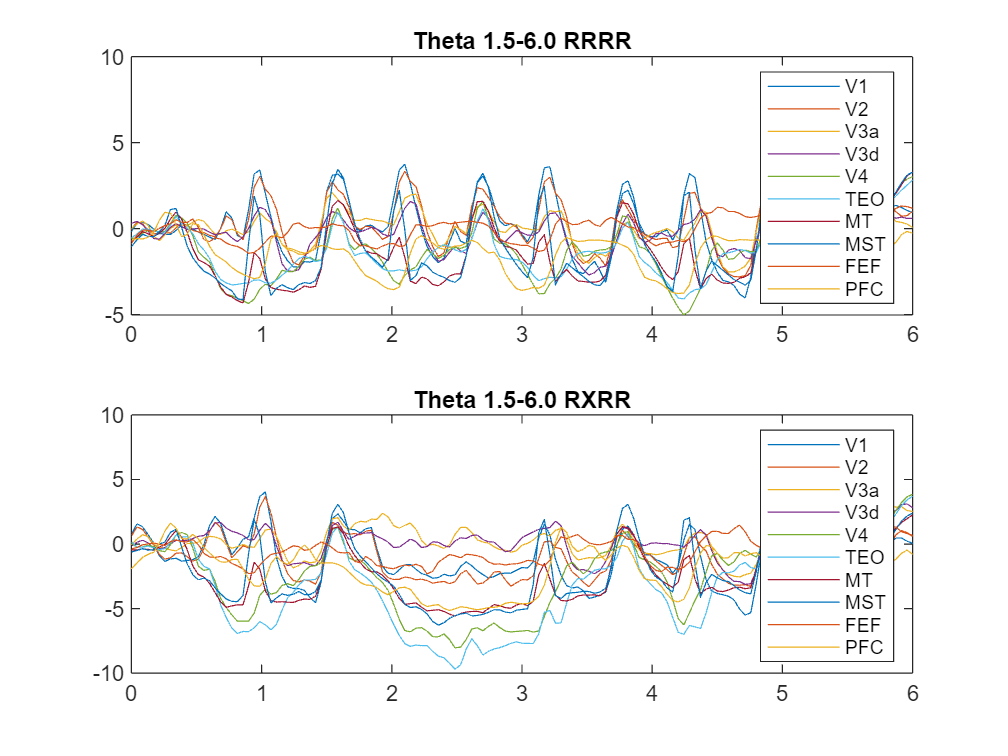

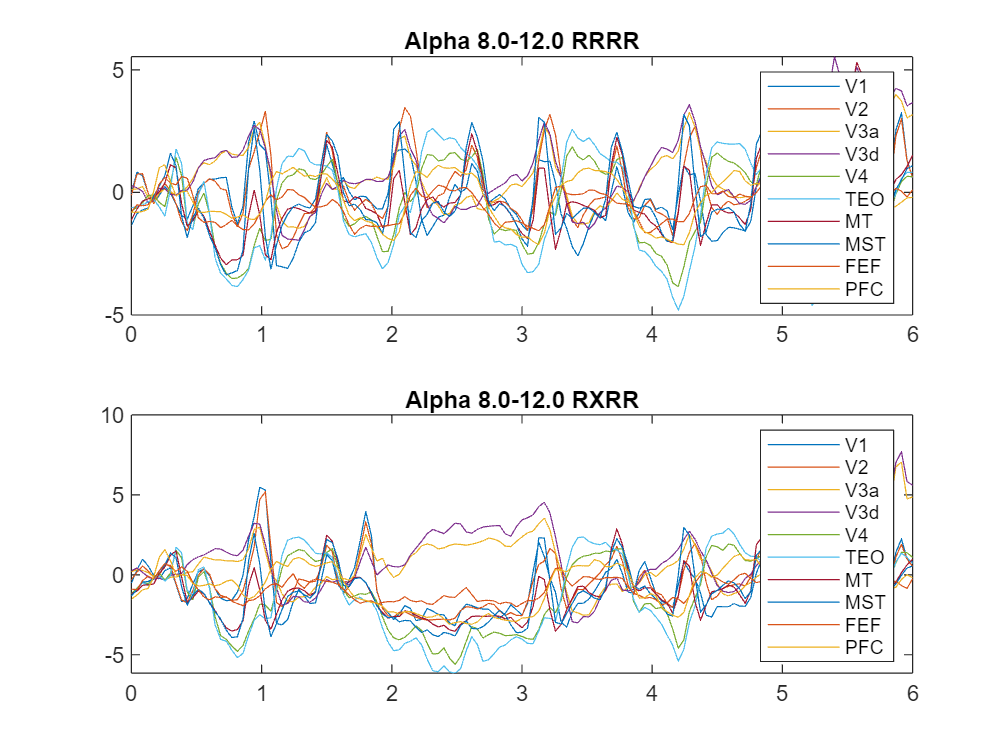

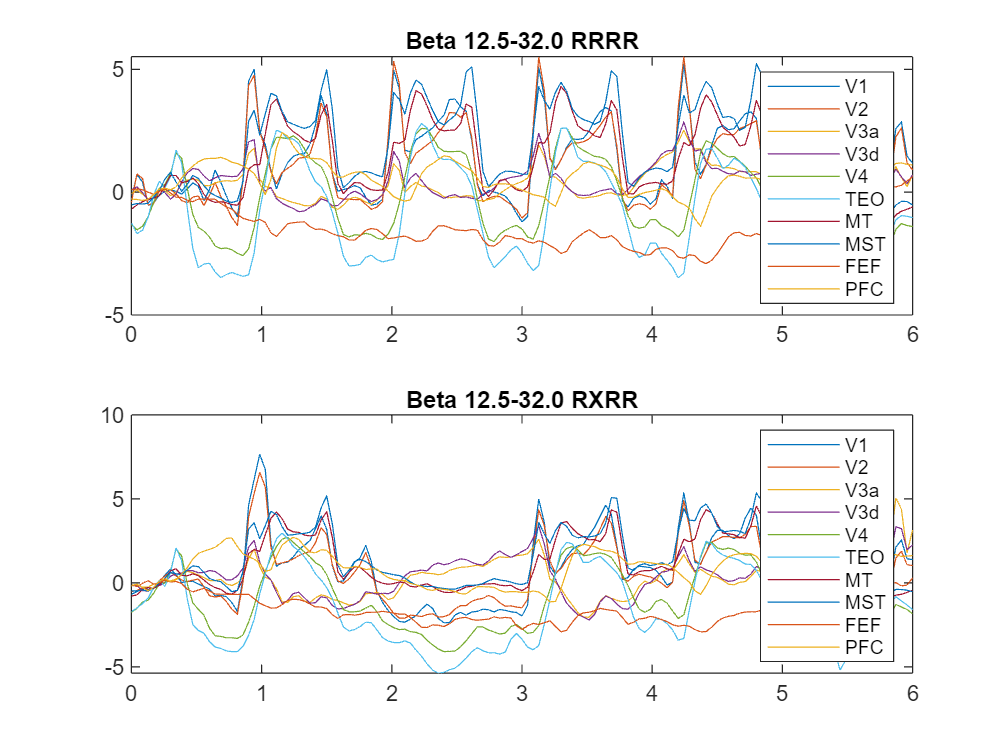

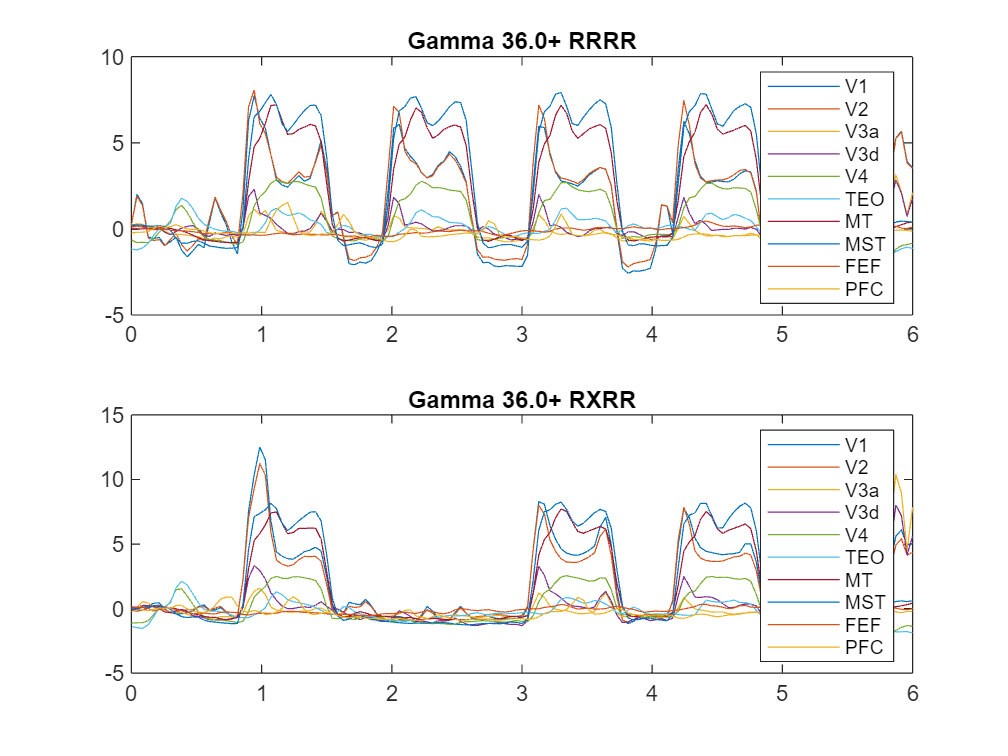

bands = ["Theta 1.5-6.0", "Alpha 8.0-12.0", "Beta 12.5-32.0", "Gamma 36.0+"];
areas = ["V1", "V2", "V3a", "V3d", "V4", "TEO", "MT", "MST", "FEF", "PFC"];
conditions = ["AAAB", "AXAB", "AAXB", "AAAX", "BBBA", "BXBA", "BBXA", "BBBX", "RRRR", "RXRR", "RRXR", "RRRX"];

for band = 1:4

    figure;
    cnts = 0;

    for cond = 9:10

        cnts = cnts + 1;
        subplot(2, 1, cnts);

        for area = 1:10
    
            plot(linspace(0, 6, 141), 10*log10(squeeze(pgxg(area, cond, band, :))), "DisplayName", areas(area));hold("on");

        end

        title(bands(band) + " " + conditions(cond));
        legend;

    end

end

pgxc = zeros(4, 12, 10, 10);

for ik = 1:4

    for jk = 1:12

        xa = log10(squeeze(pgxg(:, jk, ik, :)));
        pgxc(ik, jk, :, :) = corr(xa', "Type", "Spearman");

    end

end

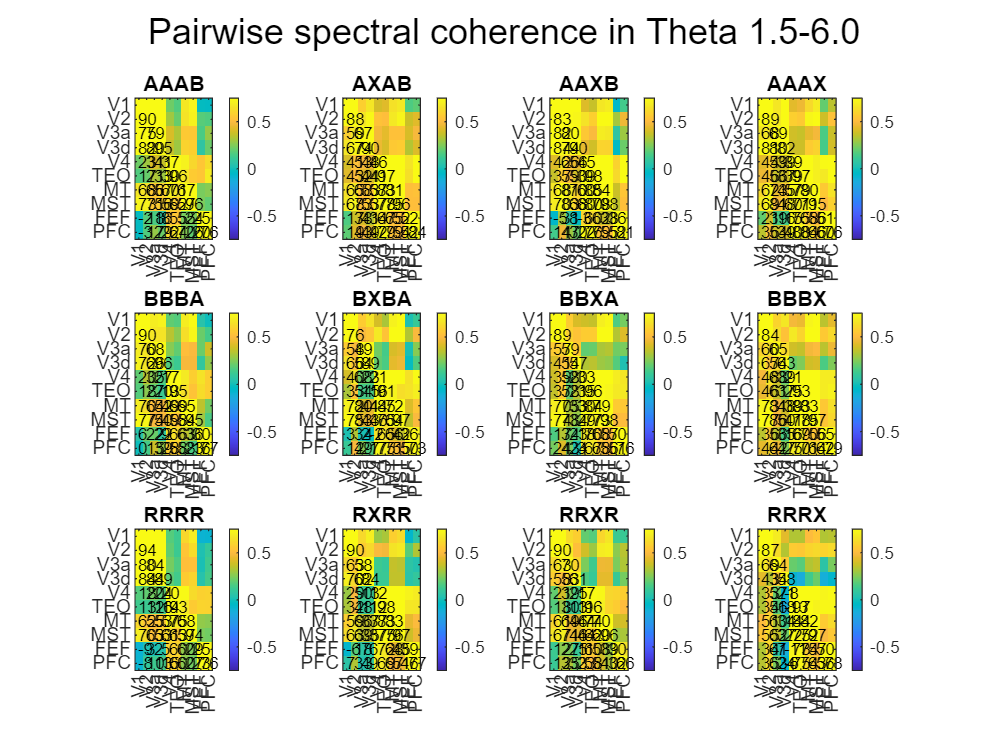

bands = ["Theta 1.5-6.0", "Alpha 8.0-12.0", "Beta 12.5-32.0", "Gamma 36.0+"];
areas = ["V1", "V2", "V3a", "V3d", "V4", "TEO", "MT", "MST", "FEF", "PFC"];
conditions = ["AAAB", "AXAB", "AAXB", "AAAX", "BBBA", "BXBA", "BBXA", "BBBX", "RRRR", "RXRR", "RRXR", "RRRX"];

ik = 1;

figure;

for jk = 1:12

    imx = squeeze(pgxc(ik, jk, :, :));
    subplot(3, 4, jk);
    imagesc(imx);clim([-0.75 0.75]);colorbar;
    hold("on");

    for kk = 1:10

        for lk = kk+1:10

            text(kk-0.1, lk, num2str(ceil(100*imx(kk, lk))), "FontSize", 7);

        end

    end
    xticks(1:10);
    xticklabels(areas);
    yticks(1:10);
    yticklabels(areas);
    title(conditions(jk));

end

sgtitle("Pairwise spectral coherence in " + bands(ik));

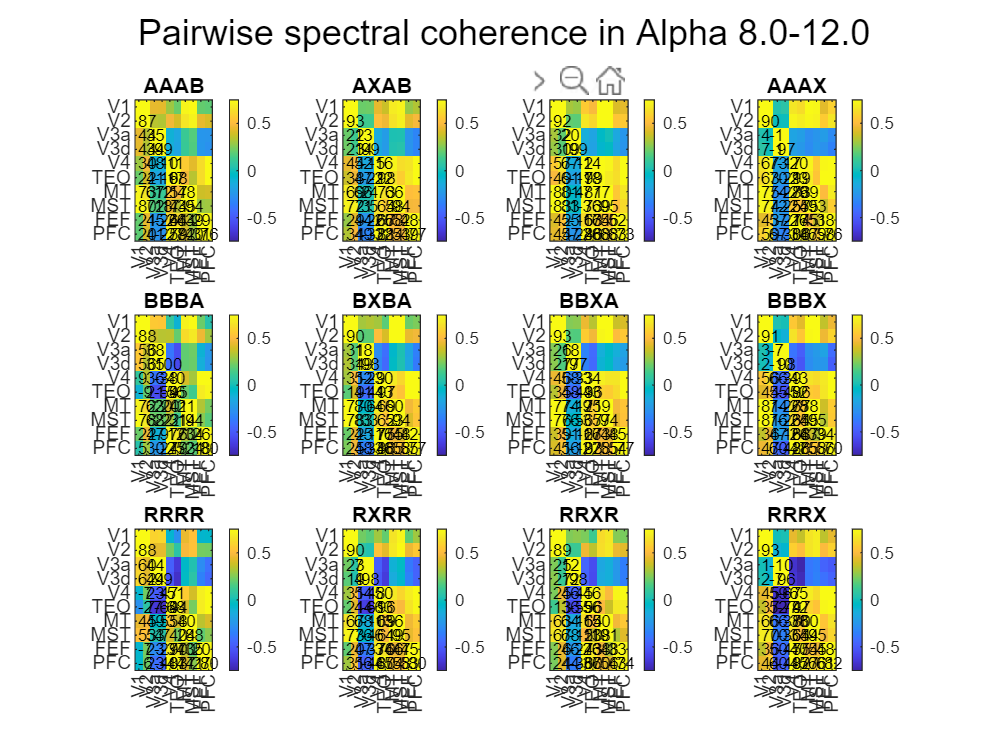

ik = 2;

figure;

for jk = 1:12

    imx = squeeze(pgxc(ik, jk, :, :));
    subplot(3, 4, jk);
    imagesc(imx);clim([-0.75 0.75]);colorbar;
    hold("on");

    for kk = 1:10

        for lk = kk+1:10

            text(kk-0.1, lk, num2str(ceil(100*imx(kk, lk))), "FontSize", 7);

        end

    end
    xticks(1:10);
    xticklabels(areas);
    yticks(1:10);
    yticklabels(areas);
    title(conditions(jk));

end

sgtitle("Pairwise spectral coherence in " + bands(ik));

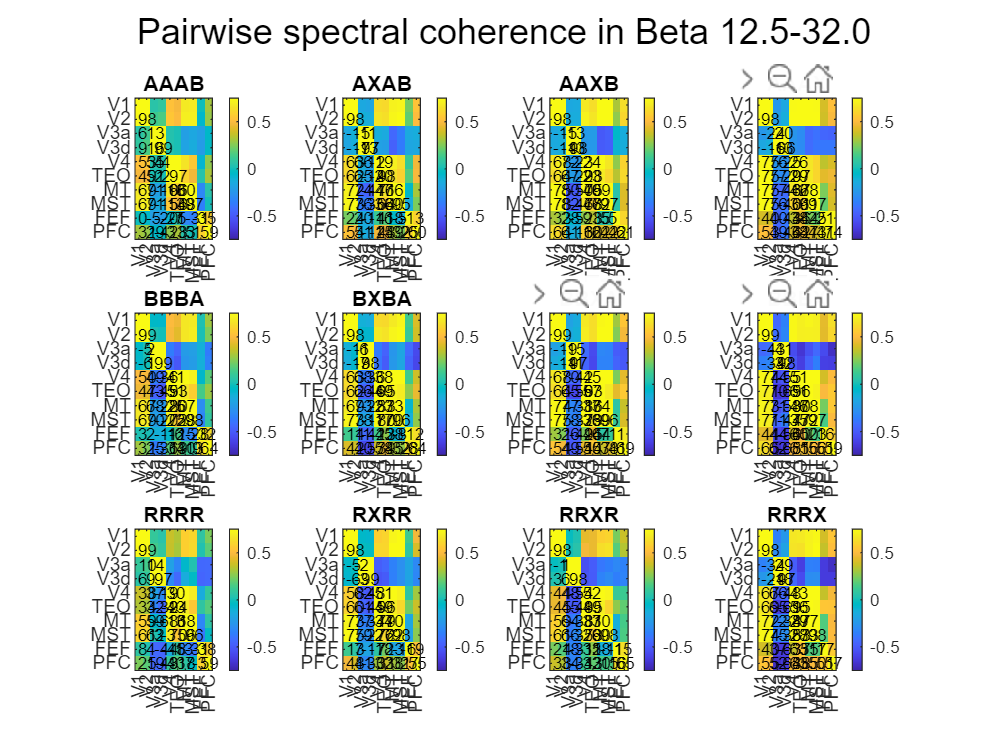

ik = 3;

figure;

for jk = 1:12

    imx = squeeze(pgxc(ik, jk, :, :));
    subplot(3, 4, jk);
    imagesc(imx);clim([-0.75 0.75]);colorbar;
    hold("on");

    for kk = 1:10

        for lk = kk+1:10

            text(kk-0.1, lk, num2str(ceil(100*imx(kk, lk))), "FontSize", 7);

        end

    end
    xticks(1:10);
    xticklabels(areas);
    yticks(1:10);
    yticklabels(areas);
    title(conditions(jk));

end

sgtitle("Pairwise spectral coherence in " + bands(ik));

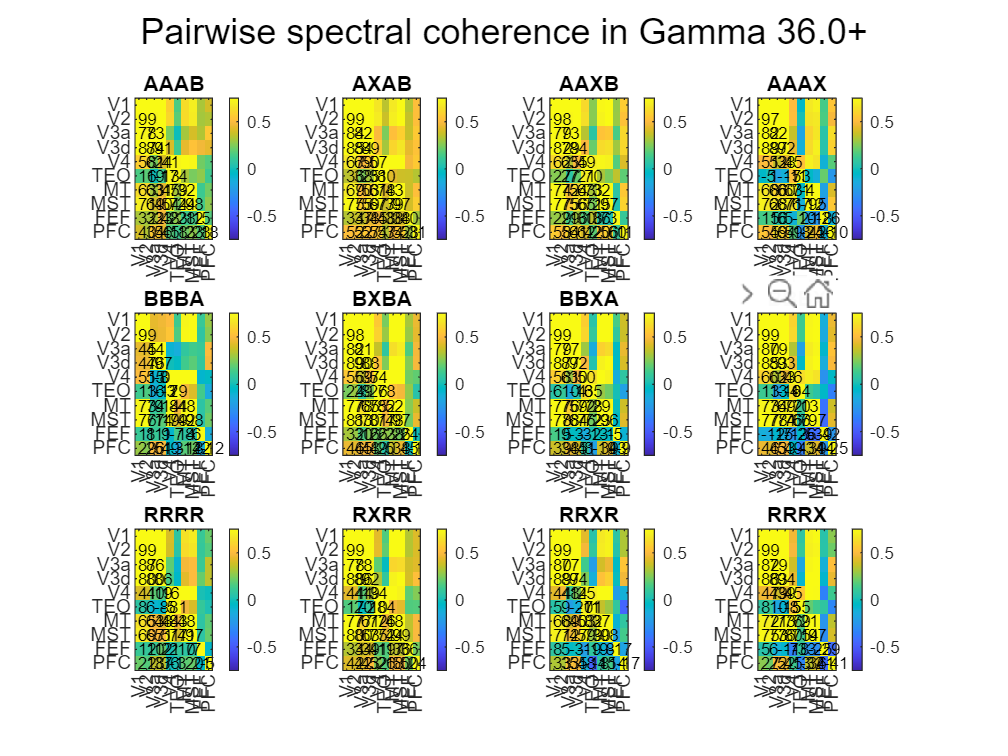

ik = 4;

figure;

for jk = 1:12

    imx = squeeze(pgxc(ik, jk, :, :));
    subplot(3, 4, jk);
    imagesc(imx);clim([-0.75 0.75]);colorbar;
    hold("on");

    for kk = 1:10

        for lk = kk+1:10

            text(kk-0.1, lk, num2str(ceil(100*imx(kk, lk))), "FontSize", 7);

        end

    end
    xticks(1:10);
    xticklabels(areas);
    yticks(1:10);
    yticklabels(areas);
    title(conditions(jk));

end

sgtitle("Pairwise spectral coherence in " + bands(ik));